syms theta1 theta2 theta3 real
syms d1 d2 real

d1_range = linspace(2,3, 50);
d2_range = linspace(2,3, 50);
theta3_range = linspace(0,2*pi, 180);

test_dh = [0 0 d1 0; 0 -pi/2 d2 pi/2; 0 -pi/2 0 theta3; 1 0 0 0;]

$$test\_dh = \left(\begin{array}{cccc} 0 & 0 & d_{1} & 0\\ 0 & -\frac{\pi }{2} & d_{2} & \frac{\pi }{2}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{3}\\ 1 & 0 & 0 & 0 \end{array}\right)$$

test_map = containers.Map({'d1', 'd2', 'theta3'},{d1_range,d2_range, theta3_range})

test_map =   Map with properties:

        Count: 3
      KeyType: char
    ValueType: any


final transformation matrix from base to end-effector:


$$\left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ -\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right) & 0 & d_{2}-\sin\left(\theta_{3}\right)\\ -\cos\left(\theta_{3}\right) & \sin\left(\theta_{3}\right) & 0 & d_{1}-\cos\left(\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

expressions for position:
x = 0
y = d2 - sin(theta3)
z = d1 - cos(theta3)
allocating 450000 possible DH parameter combinations...
calculating positions from expressions...


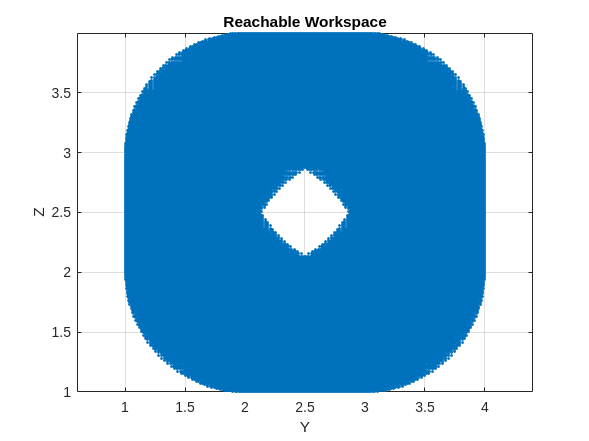

tic
plot2dworkspace(test_dh, test_map, 0.001, true)

toc

Elapsed time is 0.216831 seconds.


theta1_range = linspace(0,2*pi, 180);
theta2_range = linspace(0,2*pi, 180);

test_dh = [0 0 0 theta1; 120 0 0 theta2; 60 0 0 0;]

$$test\_dh = \left(\begin{array}{cccc} 0 & 0 & 0 & \theta_{1}\\ 120 & 0 & 0 & \theta_{2}\\ 60 & 0 & 0 & 0 \end{array}\right)$$

test_map = containers.Map({'theta1', 'theta2'},{theta1_range,theta2_range})

test_map =   Map with properties:

        Count: 2
      KeyType: char
    ValueType: any


final transformation matrix from base to end-effector:


$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 120\,\cos\left(\theta_{1}\right)+60\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-60\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 120\,\sin\left(\theta_{1}\right)+60\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+60\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{3}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

expressions for position:
x = 120*cos(theta1) + 60*cos(theta1)*cos(theta2) - 60*sin(theta1)*sin(theta2)
y = 120*sin(theta1) + 60*cos(theta1)*sin(theta2) + 60*cos(theta2)*sin(theta1)
z = 0
allocating 32400 possible DH parameter combinations...
calculating positions from expressions...


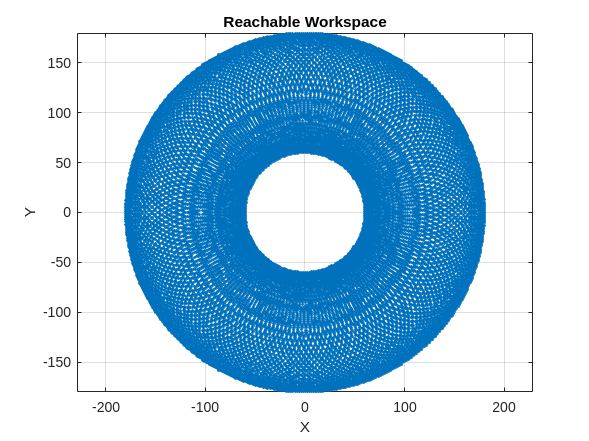

tic
plot2dworkspace(test_dh, test_map, 0.001, true)

toc

Elapsed time is 0.219382 seconds.
